clc
clear 
addpath("../") %Must add a path to where the plotting_tool is located 

%Instaiting the plotting object 
%This must be a successful run in order for this to work
X = plotting_tool("Fits/2020-10-27_11-24-54/");

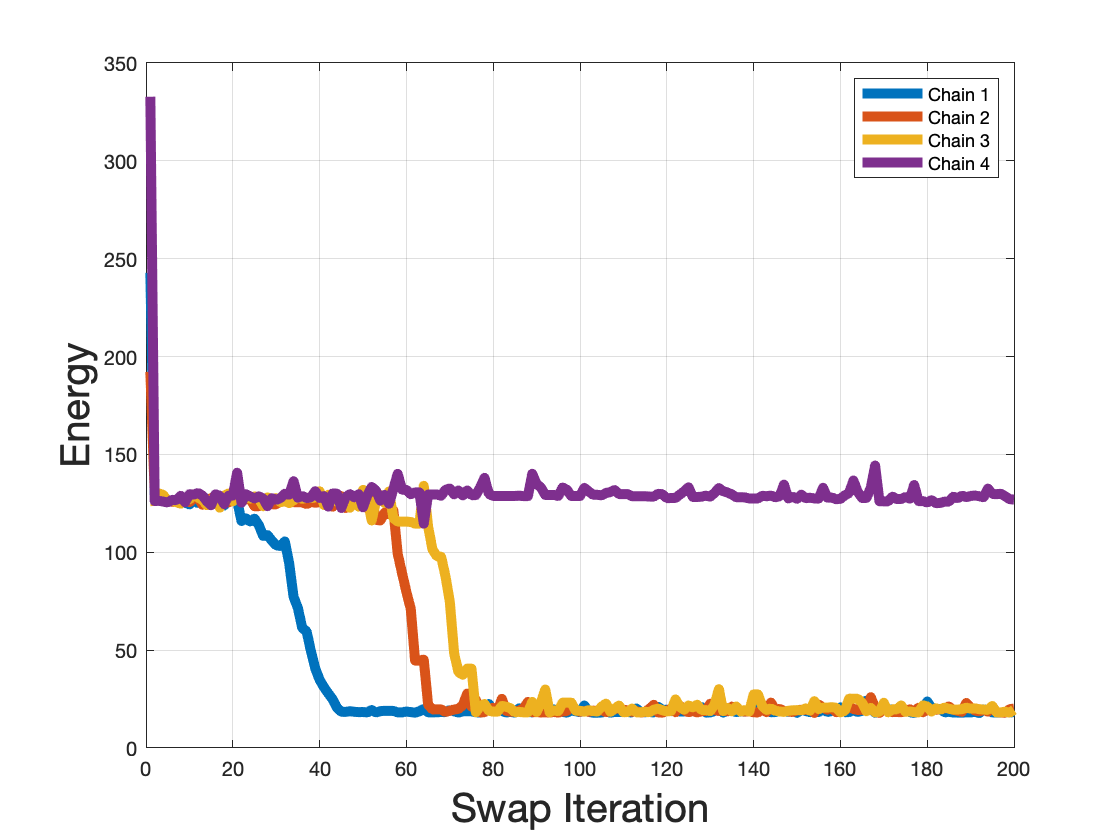

%To plot all energy chains to quickly assess the performance of the fit
X.plot_all_energy_chains()

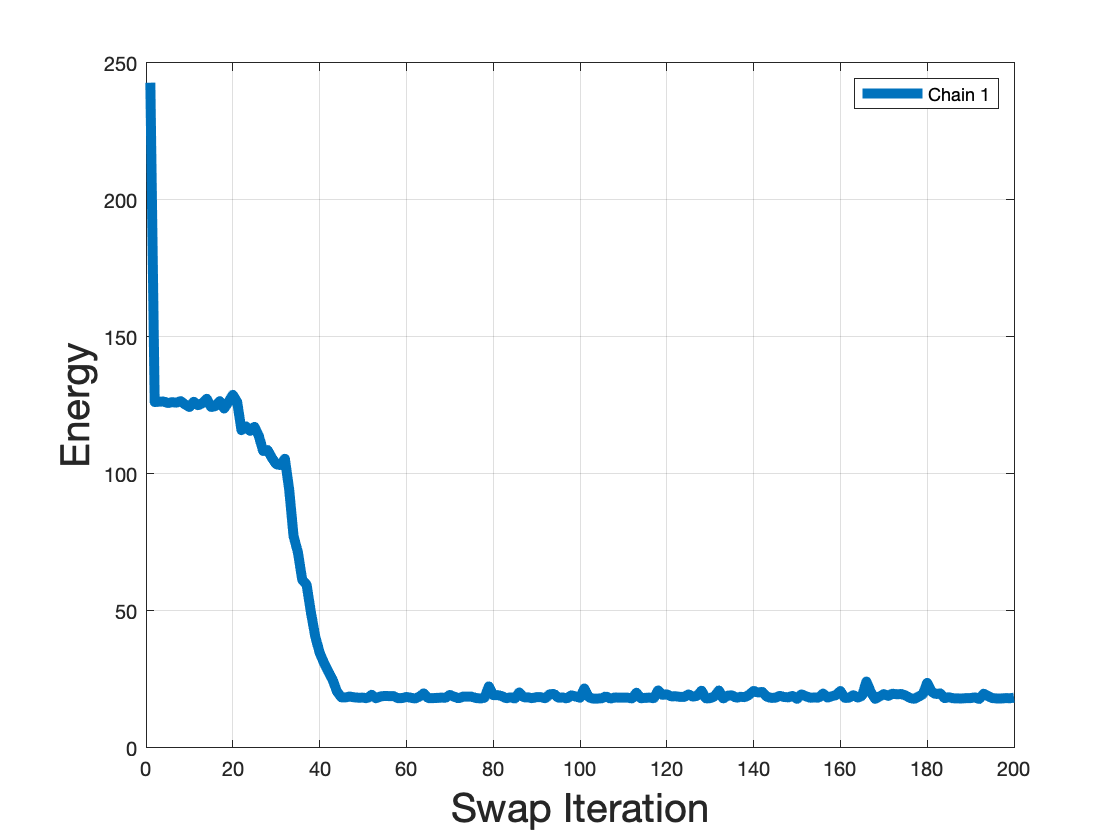

%Plot Top Energy Chain
X.plot_top_energy_chain()

%In the example above, convergence is shown to start at around iteration
%50. Therefore, the followign will tell the plotting tool to only sample
%from swap 50 and up 
X.converged_start = 50 

X =   plotting_tool with properties:

     loc_key_struct: "Fits/2020-10-27_11-24-54/"
        num_samples: 100
    converged_start: 50
       end_sampling: 200


%One can also set the number of samples to choose from. Default is set at
%100. Below I cam going to change teh default from 100 to 50

X.num_samples = 50 

X =   plotting_tool with properties:

     loc_key_struct: "Fits/2020-10-27_11-24-54/"
        num_samples: 50
    converged_start: 50
       end_sampling: 200


Need to simulate and store data
No Sampled Parameters Found!
Sampling 50 times and assuming a converged start of 50 iterations


ans =   plotting_tool with properties:

     loc_key_struct: "Fits/2020-10-27_11-24-54/"
        num_samples: 50
    converged_start: 50
       end_sampling: 200


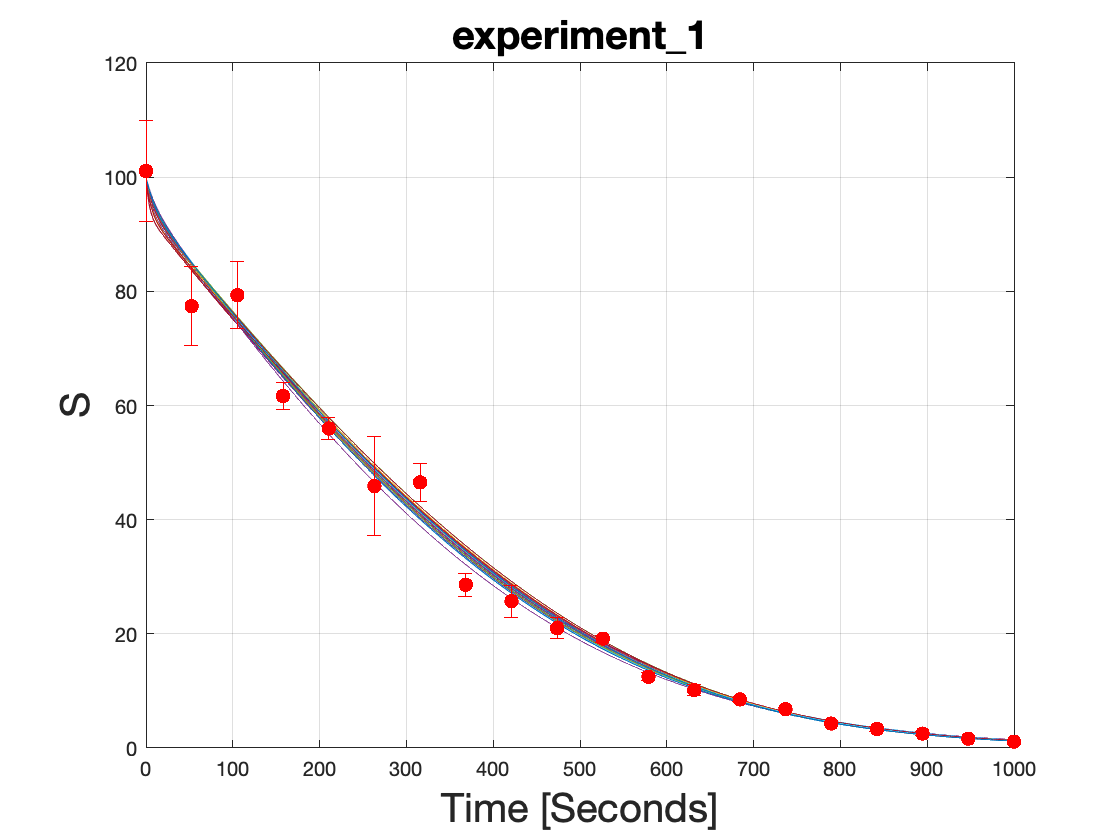

%Plot Auto will automatically plot all of your simulated  trajectories
%against your data. The first time this setting is run, the sampling and
%simulation will need to occur so the step may take awhile. After it is
%run, additional plotting will depend on previously sampled and simulated
%models. 
% 
% Multiple plots will be generated for each
%analyte/experiment combination

X.plot_auto()

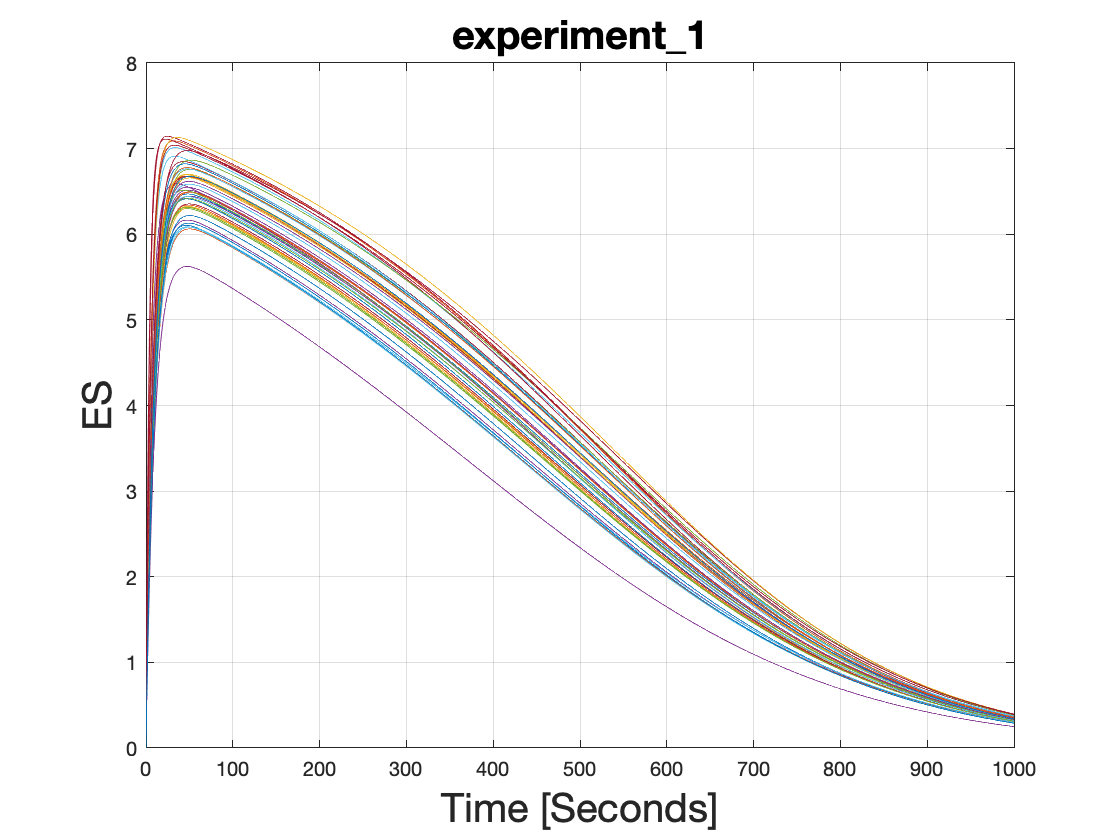

%To plot specific analytes that were not directly fit to, use the following
%code where the analyte and experiment must be exactly inputted. IF an
%error occurs, it will return values for either the analyte or experiments
%that are avaiable. 
X.plot_analyte("ES","experiment_1" )

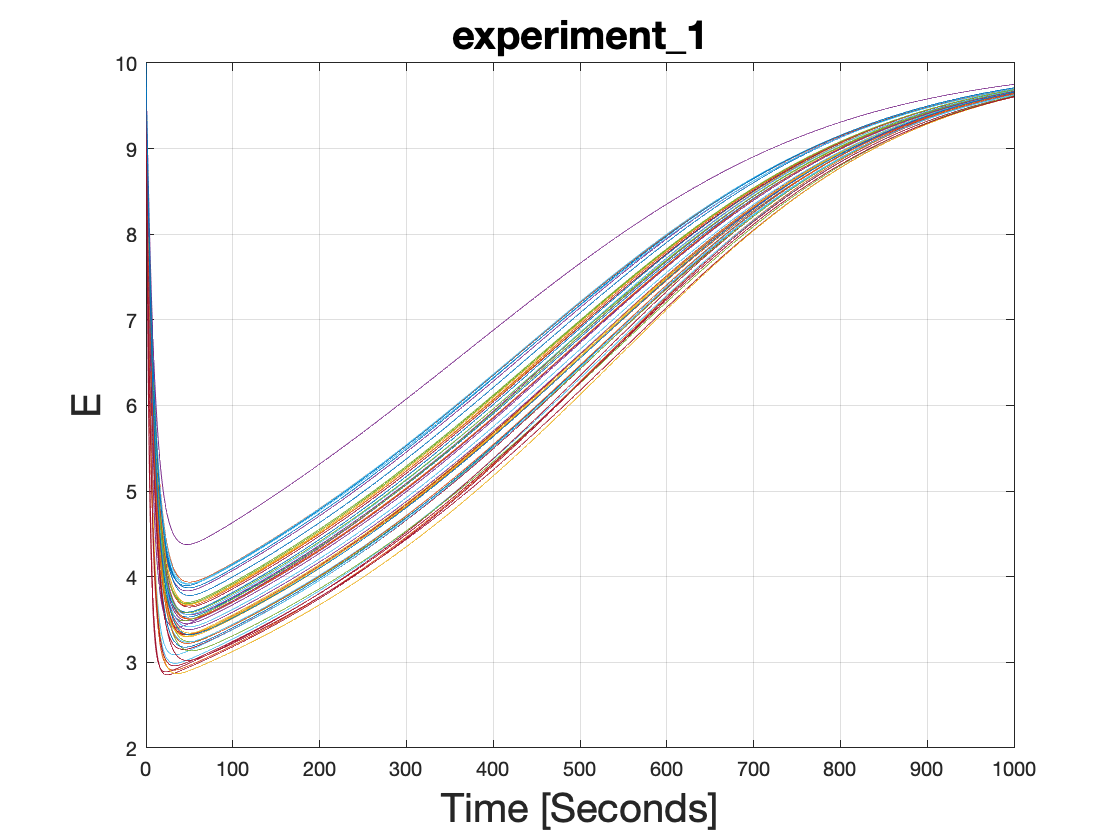

X.plot_analyte("E","experiment_1" )

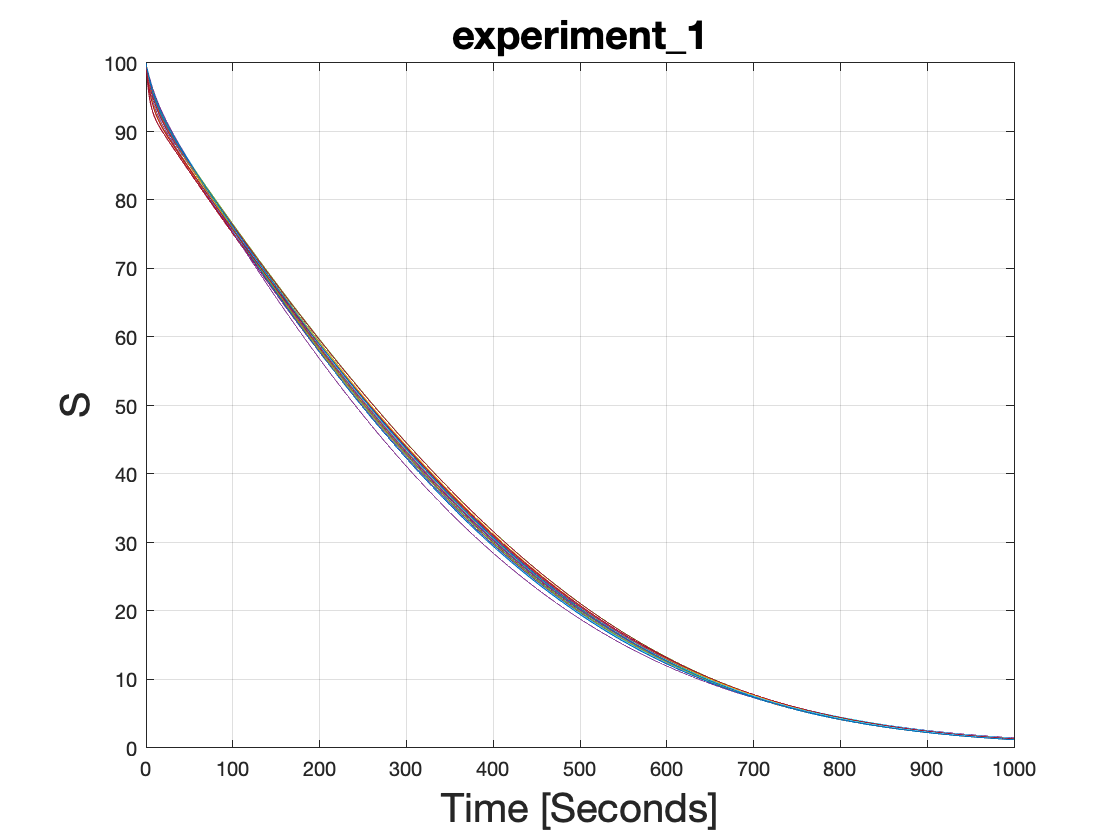

X.plot_analyte("S","experiment_1")

X.plot_analyte("ES","experiment_1" )